r = linspace(0,3000,3000);
ARef = exp(-(r./10));
HRef = sqrt(1-ARef);

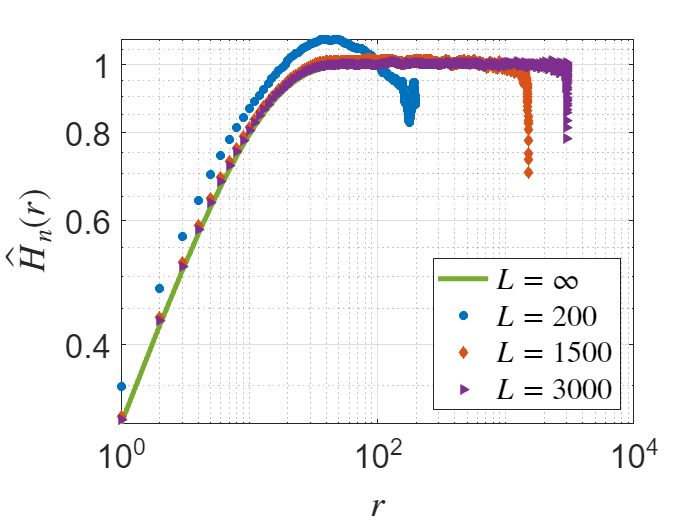

loglog(r, HRef, 'linewidth', 3, 'Color', "#77AC30")
grid on, hold on
loglog(r, mean(H(:,2,:), 3), 'o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD")
loglog(r, mean(H(:,15,:), 3), 'd', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319")
loglog(r, mean(H(:,30,:), 3), '>', 'MarkerSize',5, 'MarkerFaceColor', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E")
ylabel('$$\hat{H}_n(r)$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$r$$', 'FontSize', 22, 'Interpreter','latex')
legend('$$L=\infty$$', '$$L=200$$', ...
    '$$L=1500$$', '$$L=3000$$', "Location", 'southeast', 'Interpreter','latex', 'Orientation','vertical')
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'convergenceH1.png')

plot(r, ARef, 'linewidth', 3, 'Color', "#77AC30")
grid on, hold on
plot(r, mean(A_(:,2,:), 3), 'o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD")
plot(r, mean(A_(:,15,:), 3), 'd', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319")
plot(r, mean(A_(:,30,:), 3), '>', 'MarkerSize',5, 'MarkerFaceColor', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E")
ylabel('$$\hat{A}(r)$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$r$$', 'FontSize', 22, 'Interpreter','latex')
legend('$$L=\infty$$', '$$L=200$$', ...
    '$$L=1500$$', '$$L=3000$$', "Location", 'northeast', 'Interpreter','latex', 'Orientation','vertical')
xlim([0,200])
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'convergenceA1.png')

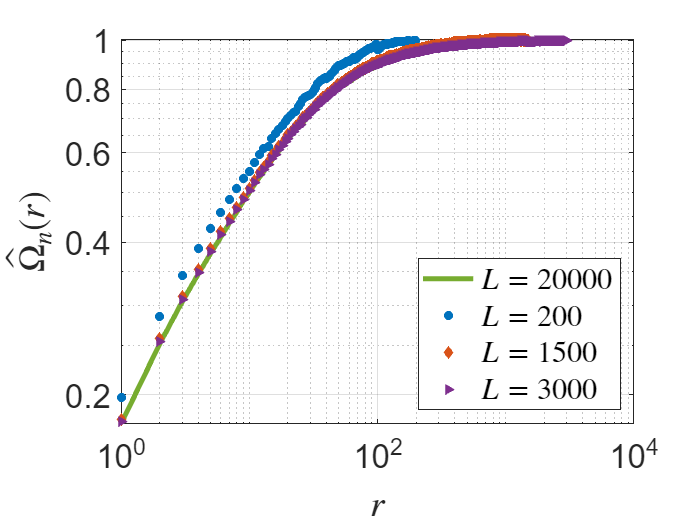

clf
loglog(r, mean(Hn(1:3000,:),2), 'linewidth', 3, 'Color', "#77AC30"), grid on, hold on
loglog(r, mean(HIW(:,2,:), 3), 'o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD")
% hold on
loglog(r, mean(HIW(:,15,:), 3), 'd', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319")
loglog(r, mean(HIW(:,30,:), 3), '>', 'MarkerSize',5, 'MarkerFaceColor', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E")
ylabel('$$\hat{\Omega}_n(r)$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$r$$', 'FontSize', 22, 'Interpreter','latex')
legend('$$L=20000$$', '$$L=200$$', ...
    '$$L=1500$$', '$$L=3000$$', "Location", 'southeast', 'Interpreter', 'latex', 'Orientation', 'vertical')
% xlim([0,200])
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'convergenceIW1.png')

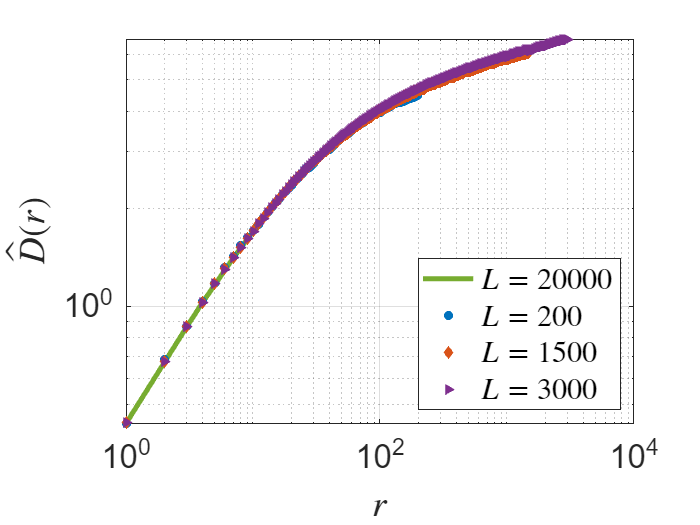

clf
loglog(r, mean(H(1:3000,:), 2), 'linewidth', 3, 'Color', "#77AC30"), grid on, hold on
loglog(r, mean(H_(:,2,:), 3), 'o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD")
% hold on
loglog(r, mean(H_(:,15,:), 3), 'd', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319")
loglog(r, mean(H_(:,30,:), 3), '>', 'MarkerSize',5, 'MarkerFaceColor', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E")
ylabel('$$\hat{D}(r)$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$r$$', 'FontSize', 22, 'Interpreter','latex')
legend('$$L=20000$$', '$$L=200$$', ...
    '$$L=1500$$', '$$L=3000$$', "Location", 'southeast', 'Interpreter', 'latex', 'Orientation', 'vertical')
% xlim([0,200])
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'convergenceD1.png')

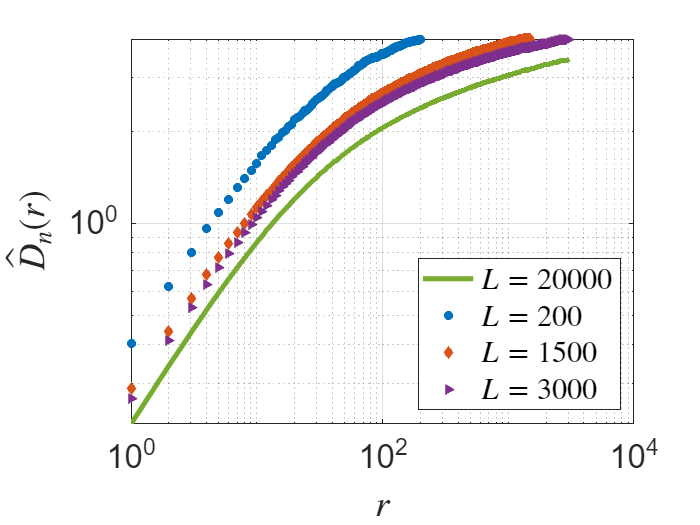

clf
loglog(r, mean(Hn(1:3000,:),2), 'linewidth', 3, 'Color', "#77AC30"), grid on, hold on
loglog(r, mean(HR(:,2,:), 3), 'o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD")
% hold on
loglog(r, mean(HR(:,15,:), 3), 'd', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319")
loglog(r, mean(HR(:,30,:), 3), '>', 'MarkerSize',5, 'MarkerFaceColor', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E")
ylabel('$$\hat{D}_n(r)$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$r$$', 'FontSize', 22, 'Interpreter','latex')
legend('$$L=20000$$', '$$L=200$$', ...
    '$$L=1500$$', '$$L=3000$$', "Location", 'southeast', 'Interpreter', 'latex', 'Orientation', 'vertical')
% xlim([0,200])
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'convergenceDn1.png')